### University of Tehran

### Department of Electrical and Computer Engineering

### Digital Communications Lab

### Fall 2020

### Y. Parhizkar

Initialization:

close all;
clear;
clc;

addpath('DigiComm-library');
run('DigiComm-library\dcl_init.m');
rng(1);

### Transmitter:

%generate messages
b_tx = bit_gen(pkt_size, k);

%create header
hder_bit = repmat(de2bi(hex2dec('1C6387FF5DA4FA32'))',1,k);
hder_bit = [hder_bit;repmat([0;de2bi(hex2dec('5C895958DC5'))'],1,k)];

%add header
b_tx = [hder_bit; b_tx];

%gray/binary code
if flg_gray_encode
    b_gray = gray_code(k);
    %convert binary to decimal for easier comparison:
    b_tx_dec = bi2de(b_tx, 'left-msb');
    b_gray_dec = bi2de(b_gray, 'left-msb');
    [~, sym_idx] = ismember(b_tx_dec, b_gray_dec);
else
    sym_idx = bi2de(b_tx, 'left-msb') + 1;
end

%modulation
[cons, Es_avg] = constellation(M, modulation);
mod_sym = cons(sym_idx);

[tx_smpl, cons] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, pulse_gen_mode, beta, span_in_symbl);

%separate and save header samples
hdr_smpl = tx_smpl(1:size(hder_bit, 1)*smpl_per_symbl);

% figure;
% stem(real(tx_smpl));
% hold on
% stem(imag(tx_smpl));
% legend('real(tx_smpl)', 'imag(tx_smpl)');
% xlabel('sample');
% title('Transmitting Digital Signal in Time Domain');

### **Channel:**

%channel delay
tx_smpl_delayed = [zeros(chnl_delay_in_smpl, 1); tx_smpl];

%channel phase offset
rx_smpl = tx_smpl_delayed .* exp(1i*chnl_phase_offset);

%channel noise
Eb = Es_avg/k;
snr_lin = 10.^(snr_db./10);
var_noise = (Eb./snr_lin);
noise_smpl = (randn(size(tx_smpl)) + 1i*randn(size(tx_smpl))) * sqrt(var_noise/2);

rx_smpl_noise = repmat(rx_smpl,1,size(noise_smpl,2)) + [zeros(chnl_delay_in_smpl, size(noise_smpl,2)); noise_smpl];

### Receiver:

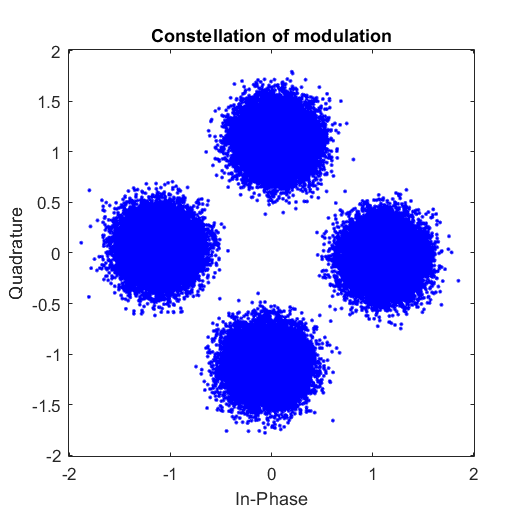

%detect channel delay
if rx_alg    
    [Rrh, lagrh] = xcorr(rx_smpl_noise(:,1), hdr_smpl);
    Rrh = Rrh(lagrh >= 0);
    [~, delay_idx] = max(abs(Rrh));
    det_delay_in_smpl = delay_idx-1;
else
    det_delay_in_smpl = chnl_delay_in_smpl;
end

%synchronization
if delay_cmpnst
    rx_smpl = rx_smpl_noise((det_delay_in_smpl+1):end, :);
else
    rx_smpl = rx_smpl_noise(1:end-det_delay_in_smpl, :);
end
    
%compensation
if cmpnst_mode == 1 || cmpnst_mode == 3
    %amplitude compensation
    
elseif cmpnst_mode == 2 || cmpnst_mode == 3
    %phase compensation
    Rh_0 = hdr_smpl' * hdr_smpl;
    rx_smpl = rx_smpl * (Rh_0/Rrh(det_delay_in_smpl));
end

%demodulation
det_sym_idx = zeros(size(sym_idx, 1), size(rx_smpl, 2));
rx_sym = zeros(size(sym_idx, 1), size(rx_smpl, 2));
for i = 1:size(rx_smpl, 2)
    [det_sym_idx(:, i), rx_sym(:, i)] = pulse_demodulation(rx_smpl(:, i), modulation, M, fs, smpl_per_symbl, pulse_name, rx_type, beta, span_in_symbl);
end

%draw constellation of recieved symbols
scatterplot(rx_sym(:, i));
title('Constellation of modulation');


%gray/binary decode
det_bit = zeros(size(det_sym_idx, 1), k, size(det_sym_idx, 2));
for i = 1:size(det_sym_idx, 2)
    if flg_gray_encode
        det_bit(:, :, i) = b_gray(det_sym_idx(:, i),:);
    else
        det_bit(:, :, i) = dec2bin(det_sym_idx(:, i)-1)-'0';
    end
end


%Symbol Error Rate
ser = sum(det_sym_idx ~= repmat(sym_idx, 1, size(sym_idx, 2)))/pkt_size;
ser = ser(:);

%Bit Error Rate
ber = sum(sum(det_bit ~= repmat(b_tx, 1, 1, size(det_bit, 3)), 1), 2)/(pkt_size*k);
ber = ber(:);

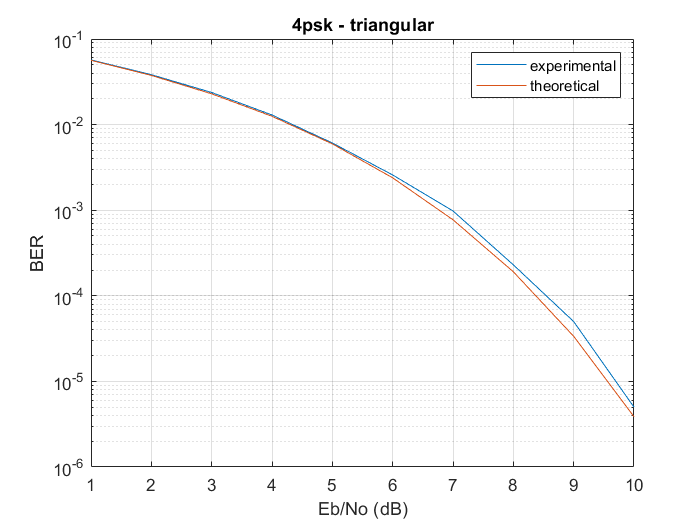

%plot ber vs Eb/No
figure;
semilogy(snr_db, ber);
hold on
if strcmp(modulation,'psk')
    semilogy(snr_db, berawgn(snr_db, modulation, M, 'nondiff'));
else
    semilogy(snr_db, berawgn(snr_db, modulation, M));
end
xlabel('Eb/No (dB)');
ylabel('BER');
title([num2str(M),modulation,' - ',pulse_name]);
legend('experimental', 'theoretical');
grid

Thanks!